# Lead

% G(s)
sysG = tf([0.129], [0.00213 0.0844 0])

sysG =
 
          0.129
  ----------------------
  0.00213 s^2 + 0.0844 s
 
Continuous-time transfer function.



% C(s)
sysGc = tf([1 40], [1 80])

sysGc =
 
  s + 40
  ------
  s + 80
 
Continuous-time transfer function.



% C(s) * G(s)
sysGcG = series(sysG, sysGc)

sysGcG =
 
            0.129 s + 5.16
  ----------------------------------
  0.00213 s^3 + 0.2548 s^2 + 6.752 s
 
Continuous-time transfer function.



% The num of C*G
num = [0.129 , 5.16];
% The den of C*G
den = [0.00213 , 0.2548 , 6.752 0];
% num of C*G for s = s_d
numval = polyval(num,-40+104.37*i);
% den of C*G for s = s_d
denval = polyval(den,-40+104.37*i);
value = denval/numval;



$$K=\frac{1}{{\left|C\left(s\right)*G\left(s\right)\right|}_{s_d } }$$


k = abs(value)

k = 206.2827

sysT1 = series(sysGcG, k)

sysT1 =
 
            26.61 s + 1064
  ----------------------------------
  0.00213 s^3 + 0.2548 s^2 + 6.752 s
 
Continuous-time transfer function.



sysT2 = series(sysGcG, 0.95*k) %It has better performance!

sysT2 =
 
            25.28 s + 1011
  ----------------------------------
  0.00213 s^3 + 0.2548 s^2 + 6.752 s
 
Continuous-time transfer function.



sysT = sysT2

sysT =
 
            25.28 s + 1011
  ----------------------------------
  0.00213 s^3 + 0.2548 s^2 + 6.752 s
 
Continuous-time transfer function.



sysTc = feedback(sysT, 1)

sysTc =
 
               25.28 s + 1011
  -----------------------------------------
  0.00213 s^3 + 0.2548 s^2 + 32.03 s + 1011
 
Continuous-time transfer function.



stepinfo(sysTc)

ans = struct with fields:
        RiseTime: 0.0130
    SettlingTime: 0.0993
     SettlingMin: 0.9018
     SettlingMax: 1.2922
       Overshoot: 29.2170
      Undershoot: 0
            Peak: 1.2922
        PeakTime: 0.0313


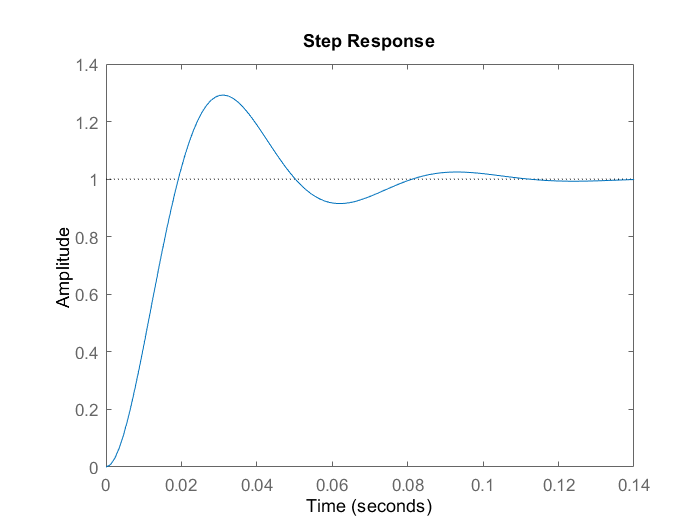

step(sysTc)

zero(sysTc)

ans = -40

pole(sysTc)

ans = 	1.0e+02 *

  -0.3978 + 1.0133i
  -0.3978 - 1.0133i
  -0.4006 + 0.0000i


syspf = tf([1], [1 40])

syspf =
 
    1
  ------
  s + 40
 
Continuous-time transfer function.



syseq = series(syspf, sysTc)

syseq =
 
                      25.28 s + 1011
  ------------------------------------------------------
  0.00213 s^4 + 0.34 s^3 + 42.22 s^2 + 2292 s + 4.045e04
 
Continuous-time transfer function.



stepinfo(syseq)

ans = struct with fields:
        RiseTime: 0.0369
    SettlingTime: 0.0990
     SettlingMin: 0.0225
     SettlingMax: 0.0250
       Overshoot: 0
      Undershoot: 0
            Peak: 0.0250
        PeakTime: 0.2072


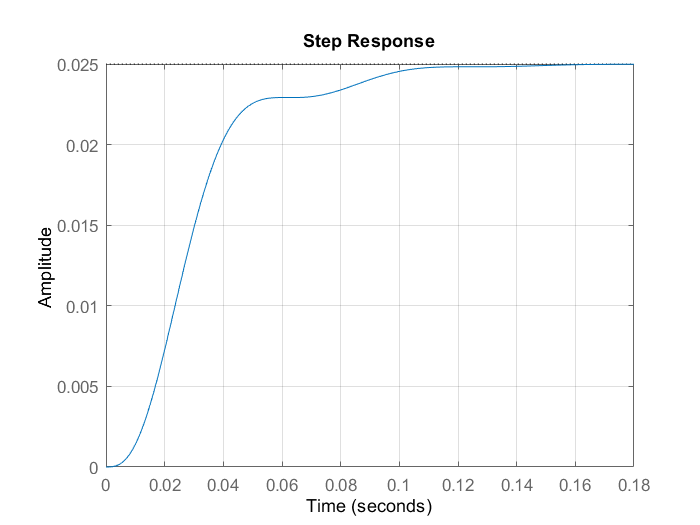

step(syseq)
grid on 
grid minor

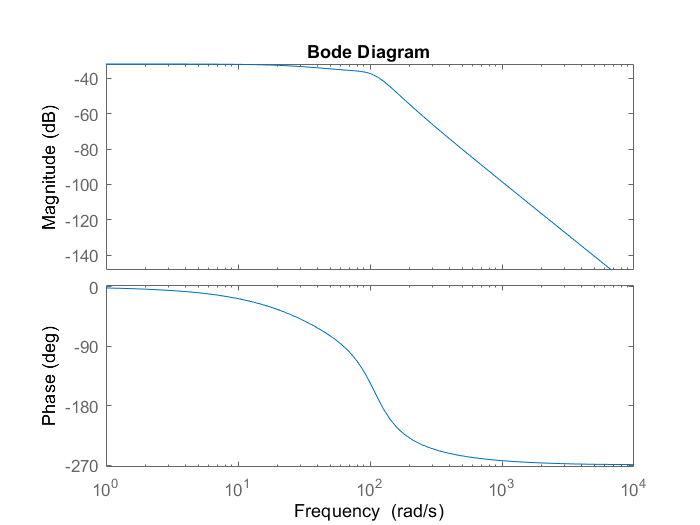

bode(syseq)

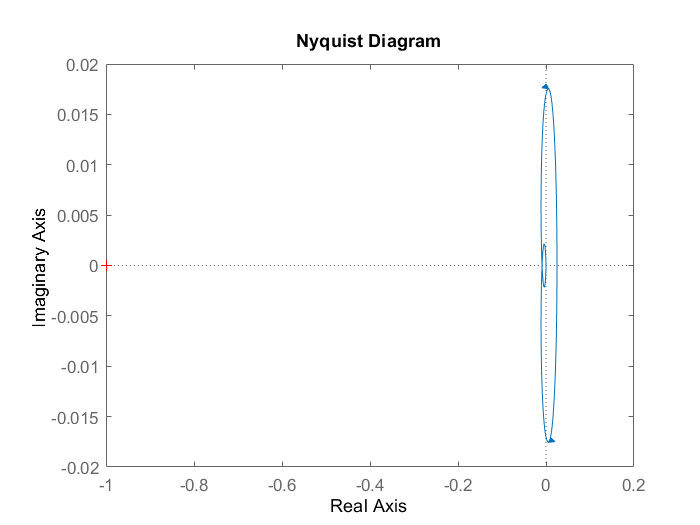

nyquist(syseq)

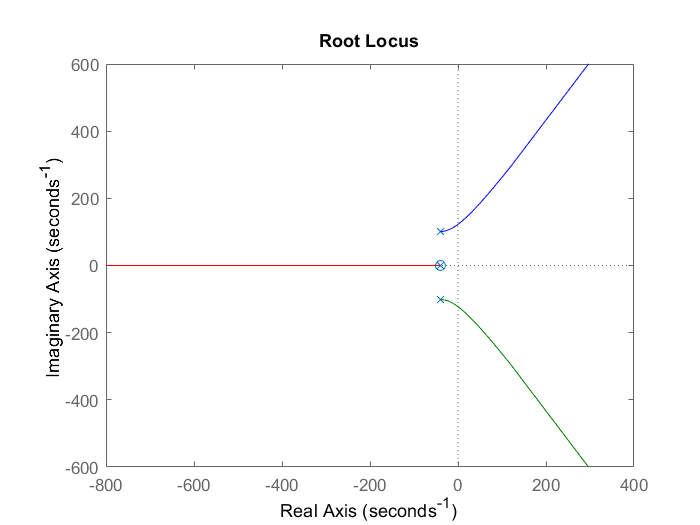

rlocus(syseq)